# Radar Pulse Compression

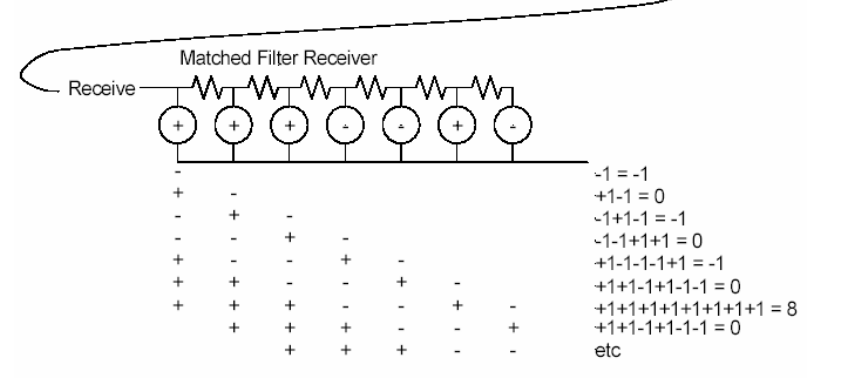

- Q. Why is pulse compression needed ?

Radar range resolution depends on the bandwidth of the received signal

$\rho =\frac{c\tau }{2}=\frac{c}{2B}$ where B is the signal bandwidth

The bandwidth of a time-gated sinusoid is inversely proportional to the pulse duration

$\to$So short pulses are better for range resolution

However, Received signal strength is proportional to the pulse duration

- So long pulses are better for signal reception

To solve this problem we can do two things

- increase $T_x$ $\to$ Require high voltage power supplies (KV), not safe

## Pulse Compression, the compromise

Transmit a long pulse that has a bandwidth coressponding to a short pulse

Must modulate or code the transmitted pulse

$\to$ To have sufficient bandwidth B

$\to$ can be processed to provide the desired range resolution $\rho$

## Example

We want the resolution be $\rho =15\mathrm{cm}$

syms tau;
tau = solve(0.15==3e8*tau/2,tau);
fprintf('pulse width = %g ',tau);

pulse width = 1e-09 

bandwidth   = 1/tau;
fprintf('bandwidth = %g',bandwidth);

bandwidth = 1e+09

So the required bandwidth is 1GHz. If we need energy of 1mJ then the Power that we need to send is


$$\begin{array}{l}
P\cdot \tau =E\;\\
1\times {10}^{-3} \;\;=1\times {10}^{-9} \;P_{t\;} \\
P_t =1\mathrm{MW}
\end{array}$$


1MW is too high !!

Pulse compression approcach

$\mathrm{Pulse}\;\mathrm{duration}\;\tau =0\ldotp 1\mathrm{ms}$ then the required transmitter power is $P=100W$

## Pulse Coding

Long duration pulse is coded to have desired bandwidth. Various ways to code pulse.

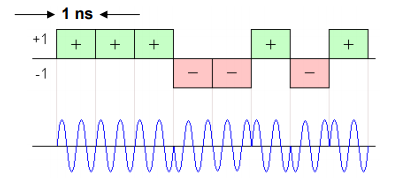

Long duration of pulse is coded to have desired bandwidth. There are varous ways to code pulses.

Phase code short segments. Each segment duration is 1ns

## Linear frequency modulation ( Chirp )

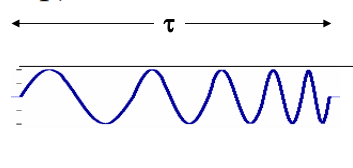

$S\left(t\right)=A\;\mathrm{cos}\;\left(2\pi f_c t+0\ldotp 5{\mathrm{kt}}^2 +\phi_c \right)$ for $0<t<\tau$

$f_c$ is the staring Frequency and k is the chirp rate, Then the bandwidth is $B=k\tau^2 =1\mathrm{GHz}$

Choice driven largely be reqired complexity of receiver electronics

Example. Starting freq = 0Hz

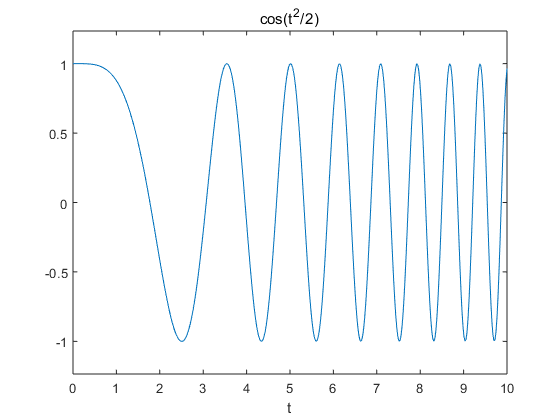

syms t y;
y = cos(0.5*t^2);
%The reason that this is a linear chirp ?
%Q. What is the freq at 5 ? 6 ? 7?
%AT t = 0 the freq is 0
% cos(2*pi*t) has a freq of ? at t=1 -> one cycle so freq is 1
% cos(50*t) has a freq of ? at t =1 -> cos(50)? cos(2*pi*T)
% cos(2*pi*f*t) then the freq is f it can be aquired by dividing with 2pi*t
ezplot(y,[0 10]);

%What is the bandwidth of this chirp ?
syms f t;
fw = int(cos(0.5*t^2)*exp(-j*2*pi*f*t),t,0,10)

$$fw = \int_{0}^{10}{\mathrm{e}}^{-2\,\pi \,f\,t\,\mathrm{i}}\,\cos\left(\frac{t^{2}}{2}\right)\mathrm{d}t$$

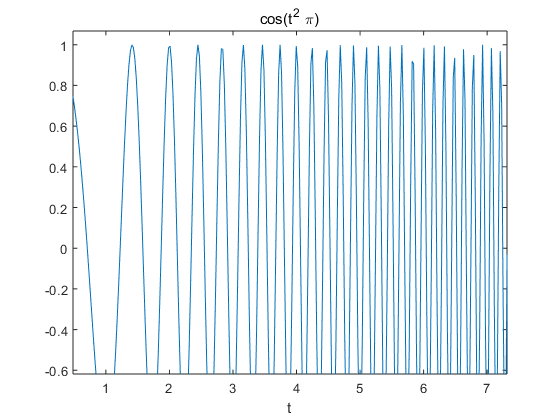

%What is the bandwidth. it starts with 0Hz, but t =10 50/(2pi)=7.96

%cannot process symbolic expression
% we change it to itndef
clear;
syms t;
ezplot(cos(0.5.*2.*pi.*t.^2),[0 10]);

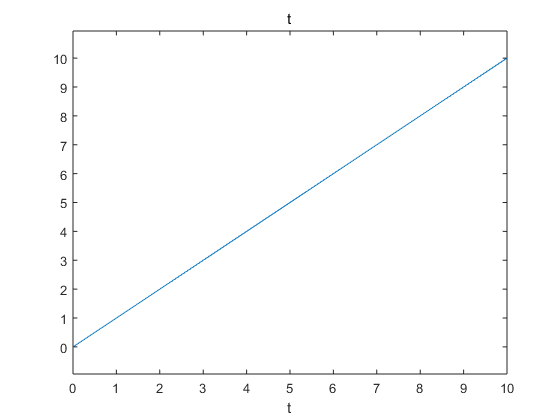

ezplot(t,[0 10]);

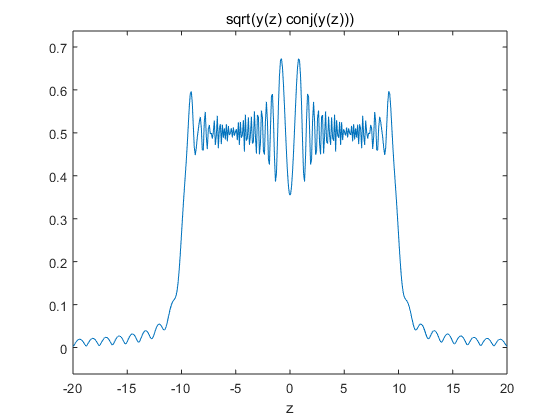

func =@(f,t) cos(0.5.*2.*pi.*t.^2).*exp(-j.*2.*pi.*t.*f);
% What is the bandwidth ? 2*pi*t and at t==10 the bandwidth is 10Hz
y =@(f) integral(@(t) func(f,t),0,10);
m =@(z) sqrt(y(z).*conj(y(z)));
ezplot(m,[-20 20]);

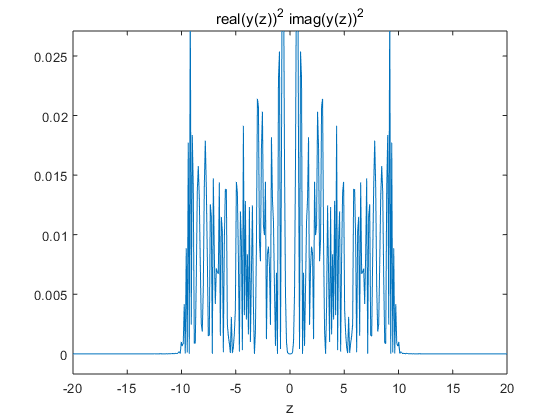

ee =@(z) real(y(z))^2 * imag(y(z))^2;
ezplot(ee,[-20 20])

%we expect pulse width is 10 so
% 2/10 = 0.2 is the bandwidth 

$B=k\tau^2$ and then $\tau =10$ So the bandwidth is 100 ?